# Bridge of Doom

Anusha Karandikar and Benji Pugh 2021.

### Calculations

Initial Calculations:

% Using the Matlab Symbolic Toolbox to solve for properties of parametric curves
clc, clear all

% Define the symbolic variables we are using
syms u

% Define the parametric equation for the path or the bridge
ri=4*(0.3960*cos(2.65*(u+1.4)));
rj=4*(-0.99*sin(u+1.4));
rk=0*u;
r=[ri,rj,rk];

% Take the derivative of the parametric equation
dr=diff(r,u);

% Unit tangent vector
T_hat_ugly=dr./norm(dr);

% Simplify the algebra
assume(u,'real') % parameter u should be real

% Simplify the unit tangent vector
T_hat=simplify(T_hat_ugly);

% Unit normal vector
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat);

Encoder Data Calculations:

data = readtable('neatodata2.csv'); %,'PreserveVariableNames',true)


% Make all data relative to first value ("zero out" the data)
encoderRightmeters = data.encoderRight_meters_ - data.encoderRight_meters_(1);
encoderLeftmeters = data.encoderLeft_meters_ - data.encoderLeft_meters_(1);
timeseconds = data.time_seconds_ - data.time_seconds_(1);

% Trim data from beginning and end of collection
encoderRightmeters = encoderRightmeters(76:200);
encoderLeftmeters = encoderLeftmeters(76:200);
timeseconds = timeseconds(76:200)-8;

% Wheelbase
wheelbase = 0.235;      % Meters

% Velocity of right and left wheels
velocity_R = diff(encoderRightmeters) ./ diff(timeseconds);     % meters/seconds
velocity_L = diff(encoderLeftmeters) ./ diff(timeseconds);      % meters/seconds

% Linear Speed
linear_experiment_speed = (velocity_L + velocity_R) / 2;

% Angular Velocity
angular_experiment_velocity = (velocity_R - velocity_L) / wheelbase;
velocity_L = diff(encoderLeftmeters) ./ diff(timeseconds);

u_points = linspace(0,3.2,4);
T_hat_values = subs(T_hat',u,u_points);
N_hat_values = subs(N_hat',u,u_points);
xy_points = subs(r',u,u_points);

syms t
rt = subs(r, u, t/3);
linear_speed = norm(diff(rt, t));
T_hat_t = diff(rt, t)/norm(diff(rt, t));
dTdt = diff(T_hat_t, t);
angular_velocity = cross(T_hat_t, dTdt);
t_points = linspace(0,3.2*3, 100);
linear_speed_points = subs(linear_speed, t, t_points);
angular_velocity_points = subs(angular_velocity', t, t_points);

left_wheel_velocity = linear_speed - angular_velocity(:,3)*wheelbase/2;
right_wheel_velocity = linear_speed + angular_velocity(:,3)*wheelbase/2;
left_velocity_points = subs(left_wheel_velocity',t,t_points);
right_velocity_points = subs(right_wheel_velocity',t,t_points);

starting_T_hat = double(subs(T_hat, u, 0));
starting_theta = atan(starting_T_hat(2)/starting_T_hat(1));
starting_position = double(subs(r(1:2), u, 0));
theta_experimental = [starting_theta];
position_experimental = [starting_position];

for i = 1:length(angular_experiment_velocity)
    delta_t = diff(timeseconds);
    next_angle = theta_experimental(i) + (angular_experiment_velocity(i))*(delta_t(i));
    theta_experimental = [theta_experimental; next_angle];
end
for i = 1:length(linear_experiment_speed)
    delta_t = diff(timeseconds);
    experimental_T_hat = [cos(theta_experimental(i)), sin(theta_experimental(i))];
    change = linear_experiment_speed(i).*experimental_T_hat*delta_t(i);
    next_position = position_experimental(i,:) + change;
    position_experimental = [position_experimental; next_position];
end

### 21.1

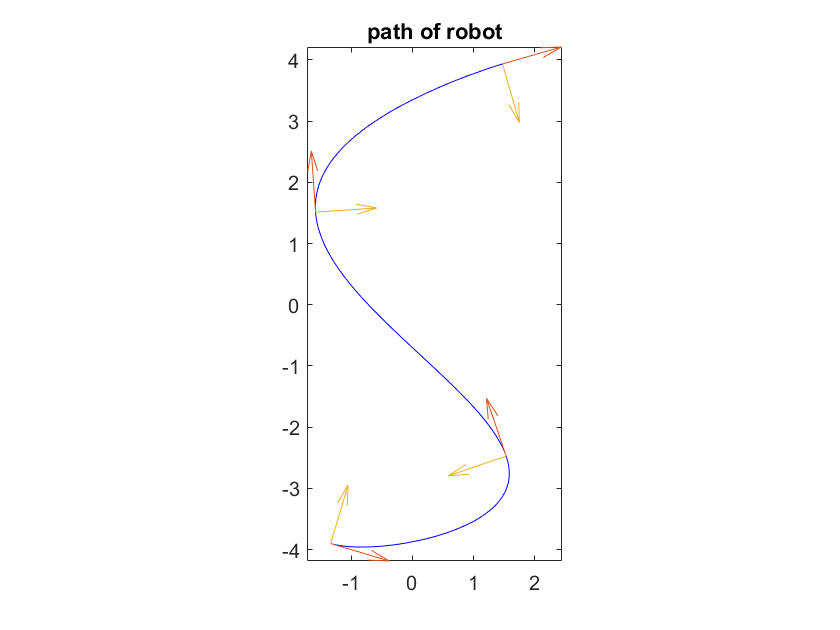

% Plot parametric curve
clf
fplot(ri,rj,[0,3.2],'b-');
axis equal
hold on
title("path of robot")
quiver(xy_points(1,:)',xy_points(2,:)',T_hat_values(1,:)',T_hat_values(2,:)', 0);
quiver(xy_points(1,:)',xy_points(2,:)',N_hat_values(1,:)',N_hat_values(2,:)', 0);
hold off

### 21.2

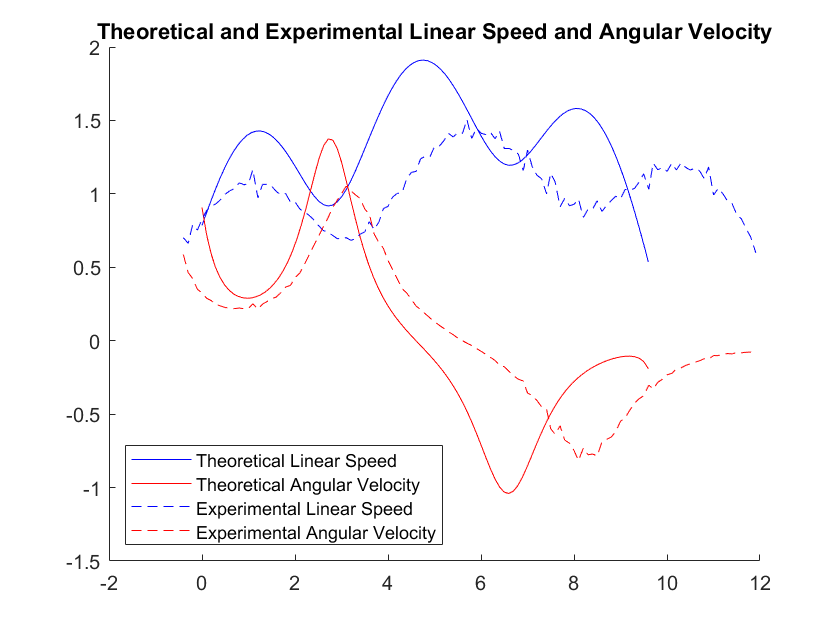

% Plot the theoretical and experimental linear speed and angular velocity
clf
hold on
plot(t_points,linear_speed_points,'b-')
plot(t_points, angular_velocity_points(3,:)','r-')
plot(timeseconds(2:end), linear_experiment_speed,'b--')
plot(timeseconds(2:end), angular_experiment_velocity,'r--')
title("Theoretical and Experimental Linear Speed and Angular Velocity")
legend("Theoretical Linear Speed","Theoretical Angular Velocity", ...
    "Experimental Linear Speed","Experimental Angular Velocity",'Location','southwest')
hold off

### 21.3

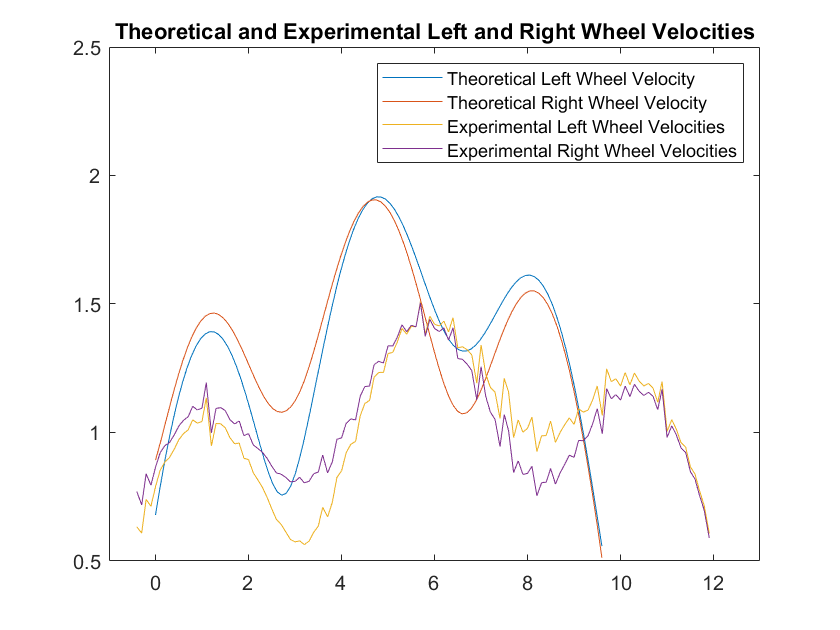

plot(t_points,left_velocity_points)
hold on
plot(t_points,right_velocity_points)
%timeseconds = timeseconds(76:200);
plot(timeseconds(2:end), velocity_L)
plot(timeseconds(2:end), velocity_R)
title("Theoretical and Experimental Left and Right Wheel Velocities")
legend('Theoretical Left Wheel Velocity','Theoretical Right Wheel Velocity', ...
    'Experimental Left Wheel Velocities','Experimental Right Wheel Velocities')
axis([-1 13 0.5 2.5])
hold off

### 21.5

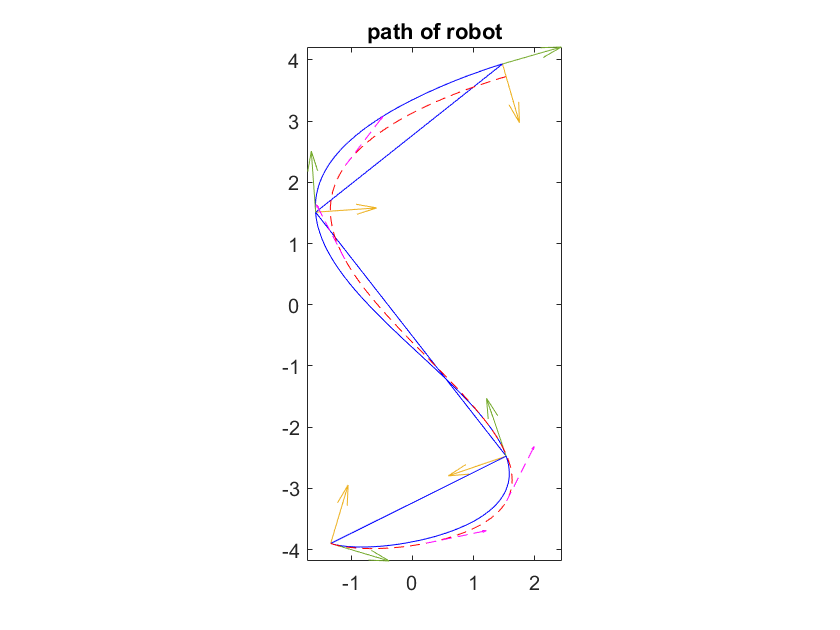

axis equal
hold on
title("path of robot")
plot((xy_points(1,:))',(xy_points(2,:)'),'b-')
quiver(xy_points(1,:)',xy_points(2,:)',T_hat_values(1,:)',T_hat_values(2,:)', 0);
plot(position_experimental(:,1), position_experimental(:,2),'r--')
quiver(position_experimental(18,1),position_experimental(18,2), cos(theta_experimental(18)), sin(theta_experimental(18)), 0, 'm--')
quiver(position_experimental(35,1),position_experimental(35,2), cos(theta_experimental(35)), sin(theta_experimental(35)),0, 'm--')
quiver(position_experimental(78,1),position_experimental(78,2), cos(theta_experimental(78)), sin(theta_experimental(78)),0, 'm--')
quiver(position_experimental(95,1),position_experimental(95,2), cos(theta_experimental(95)), sin(theta_experimental(95)),0, 'm--')
hold off